# Actividad 1.5 (Evaluación)

Pamela Hernández Montero A01736368

**Instrucciones: **Implementar el código requerido para generar las siguientes trayectorias a partir de las velocidades angulares y lineales en un plano 2D.

**Trayectoria 1:**

X= [0 a 5]

F(x) = 2*sen(x^(1.5))

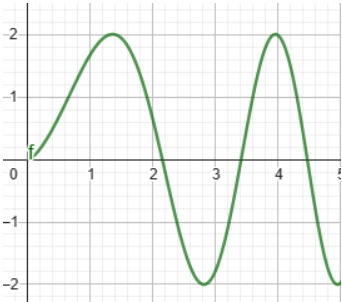

Esta trayectoria fue difícil de calcular debido a que la función seno depende de la velocidad angular y lineal al mismo tiempo para poder crear las curvaturas de la trayectoria. En este caso, decidí definir los picos como las coordenadas donde el robot quería llegar, siendo (1.3, 2), después a (2.8, -2), luego a (3.8, 2) y finalmente a (4.9, -2)

clear
close all
clc

El tiempo de muestreo lo defini entre cada rotacion y punto para llegar al final.

%%% TIEMPO %%%

% Definición de parámetros de tiempo
tf = 8;             % Tiempo de simulación en segundos (s)
ts = 1;              % Tiempo de muestreo en segundos (s)

% Creación del vector de tiempo
t = 0:ts:tf;         % Vector de tiempo
N = length(t);       % Número de muestras

%%% CONDICIONES INICIALES %%%

x1 = zeros (1,N+1);  % Posición en el centro del eje que une las ruedas (eje x) en metros (m)
y1 = zeros (1,N+1);  % Posición en el centro del eje que une las ruedas (eje y) en metros (m)
phi = zeros(1, N+1); % Orientacion del robot en radianes (rad)

x1(1) = 0;    % Posición inicial eje x
y1(1) = 0;   % Posición inicial eje y
phi(1) = 0;   % Orientación inicial del robot

%%% PUNTO DE CONTROL %%%

hx = zeros(1, N+1);  % Posición en el punto de control (eje x) en metros (m)
hy = zeros(1, N+1);  % Posición en el punto de control (eje y) en metros (m)

hx(1) = x1(1); % Posición en el punto de control del robot en el eje x
hy(1) = y1(1); % Posición en el punto de control del robot en el eje y

odas las velocidades angulares las determiné por método heurístico, modificando ángulos y observando cuáles se adecuaban mejor al punto deseado. Por otro lado, para determinar las velocidades lineales, creé triángulos para poder determinar la hipotenusa que representa la distancia entre cada punto.

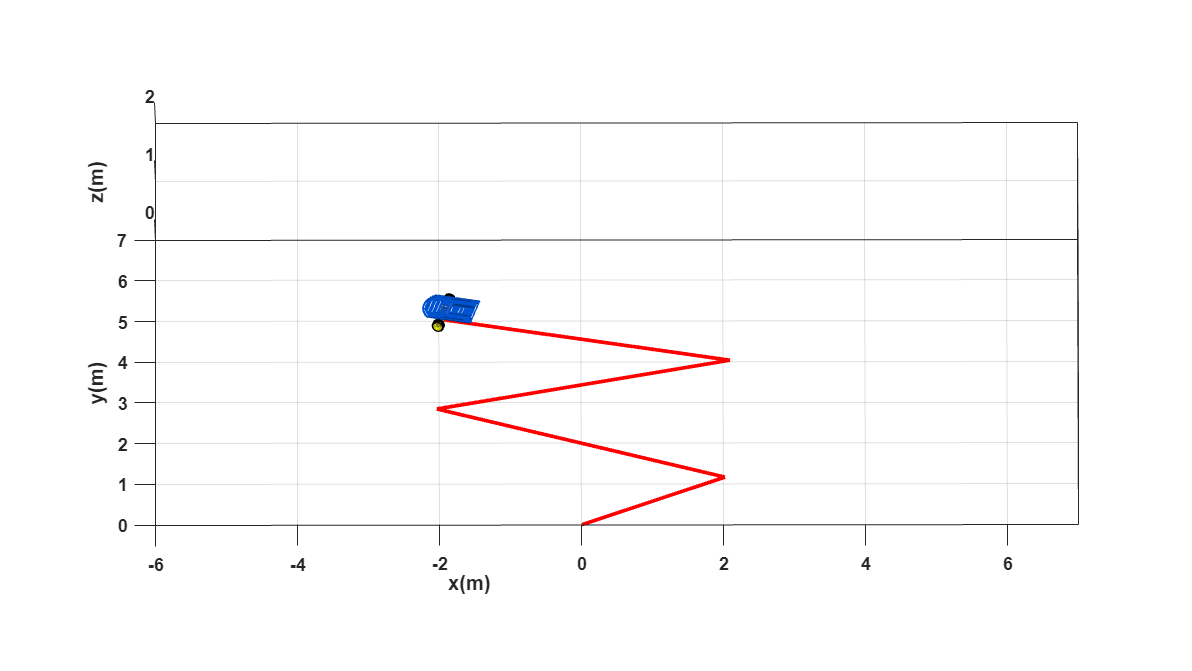

%%% VELOCIDADES DE REFERENCIA %%% 
u = [ 0  , 2.33,  0        , 4.39  ,  0         , 4.3 , 0         , 4.15, 0 ]; % Velocidad lineal de referencia (m/s)
w = [pi/6,  0  , pi/2+pi/4.8 , 0     , -pi/2-pi/3.5 , 0    ,  pi/2+pi/3, 0   , 0 ]; % Velocidad angular de referencia (rad/s)

%%% BUCLE DE SIMULACIÓN %%% 
for k=1:N 
    
    phi(k+1)=phi(k)+w(k)*ts; % Integral numérica (método de Euler)
    
    % MODELO CINEMATICO 
    xp1=u(k)*cos(phi(k+1)); 
    yp1=u(k)*sin(phi(k+1));

    x1(k+1)=x1(k) + xp1*ts ; % Integral numérica (método de Euler)
    y1(k+1)=y1(k) + yp1*ts ; % Integral numérica (método de Euler)
    
    % Posición del robot con respecto al punto de control
    hx(k+1)=x1(k+1); 
    hy(k+1)=y1(k+1);

end

% SIMULACION VIRTUAL 3D

% a) Configuración de escena
scene=figure;  % Crear figura (Escena)
set(scene,'Color','white'); % Color del fondo de la escena
set(gca,'FontWeight','bold') ;% Negrilla en los ejes y etiquetas
sizeScreen=get(0,'ScreenSize'); % Retorna el tamaño de la pantalla del computador
set(scene,'position',sizeScreen); % Congigurar tamaño de la figura
camlight('headlight'); % Luz para la escena
axis equal; % Establece la relación de aspecto para que las unidades de datos sean las mismas en todas las direcciones.
grid on; % Mostrar líneas de cuadrícula en los ejes
box on; % Mostrar contorno de ejes
xlabel('x(m)'); ylabel('y(m)'); zlabel('z(m)'); % Etiqueta de los eje

view([-0.1 35]); % Orientacion de la figura
axis([-6 7 0 7 0 2]); % Ingresar limites minimos y maximos en los ejes x y z [minX maxX minY maxY minZ maxZ]

% b) Graficar robots en la posicion inicial
scale = 4;
MobileRobot_5;
H1=MobilePlot_4(x1(1),y1(1),phi(1),scale);hold on;

% c) Graficar Trayectorias
H2=plot3(hx(1),hy(1),0,'r','lineWidth',2);

% d) Bucle de simulacion de movimiento del robot

step=1; % pasos para simulación

for k=1:step:N

    delete(H1);    
    delete(H2);
    
    H1=MobilePlot_4(x1(k),y1(k),phi(k),scale);
    H2=plot3(hx(1:k),hy(1:k),zeros(1,k),'r','lineWidth',2);
    
    pause(ts);

end

Algo que se me ocurre para poder adecuar la trayectoria a la deseada es implementar una función dentro de la velocidad lineal que aumente o disminuya la velocidad con respecto al tiempo, para poder hacer una curvatura parecida a la que tiene la función.

**Trayectoria 2:**

X= [0 a 9]

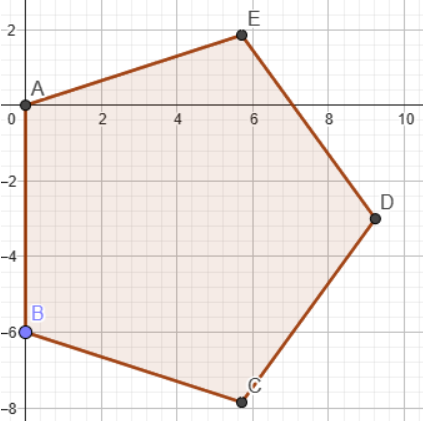

clear
close all
clc

Para poder hacer el pentágono, opté por definir un tiempo de simulación de 10 segundos considerando que al final se requiere un movimiento extra para que la simulación realice el último movimiento.

%%% TIEMPO %%%
 
% Definición de parámetros de tiempo
tf = 10;             % Tiempo de simulación en segundos (s)
ts = 1;              % Tiempo de muestreo en segundos (s)

% Creación del vector de tiempo
t = 0:ts:tf;         % Vector de tiempo
N = length(t);       % Número de muestras

Como condiciones iniciales, opté por empezar con 0 en todo, donde x1 y y1 representan el punto A del pentágono y donde, al observar la orientación inicial, es más fácil determinar el ángulo para moverse al punto B en (0,-6).

%%% CONDICIONES INICIALES %%%

x1 = zeros (1,N+1);  % Posición en el centro del eje que une las ruedas (eje x) en metros (m)
y1 = zeros (1,N+1);  % Posición en el centro del eje que une las ruedas (eje y) en metros (m)
phi = zeros(1, N+1); % Orientacion del robot en radianes (rad)

x1(1) = 0;    % Posición inicial eje x
y1(1) = 0;   % Posición inicial eje y
phi(1) = 0;   % Orientación inicial del robot

%%% PUNTO DE CONTROL %%%

hx = zeros(1, N+1);  % Posición en el punto de control (eje x) en metros (m)
hy = zeros(1, N+1);  % Posición en el punto de control (eje y) en metros (m)

hx(1) = x1(1); % Posición en el punto de control del robot en el eje x
hy(1) = y1(1); % Posición en el punto de control del robot en el eje y

Primero encontré el ángulo correcto para que el robot bajara al punto B. Una vez llegado a este punto, busqué la rotación correcta para que llegase al punto C en (9,-3). Posteriormente, debido a que todos los lados del pentágono son iguales, así como sus ángulos, hice los trazos restantes para marcar todos los lados, para finalmente verificar que llegara al origen y mostrara el pentágono.

%%% VELOCIDADES DE REFERENCIA %%% 
u = [   0    , 6 ,   0    , 6 ,   0    , 6 ,    0    , 6 ,   0    , 6 , 0 ]; % Velocidad lineal de referencia (m/s)
w = [ 3*pi/2 , 0 , pi/2.5 , 0 , pi/2.5 , 0 ,  pi/2.5 , 0 , pi/2.5 , 0 , 0 ]; % Velocidad angular de referencia (rad/s)


%%% BUCLE DE SIMULACIÓN %%% 
for k=1:N 
    
    phi(k+1)=phi(k)+w(k)*ts; % Integral numérica (método de Euler)
    
    % MODELO CINEMATICO 
    xp1=u(k)*cos(phi(k+1)); 
    yp1=u(k)*sin(phi(k+1));

    x1(k+1)=x1(k) + xp1*ts ; % Integral numérica (método de Euler)
    y1(k+1)=y1(k) + yp1*ts ; % Integral numérica (método de Euler)
    
    % Posición del robot con respecto al punto de control
    hx(k+1)=x1(k+1); 
    hy(k+1)=y1(k+1);

end

% SIMULACION VIRTUAL 3D

% a) Configuración de escena
scene=figure;  % Crear figura (Escena)
set(scene,'Color','white'); % Color del fondo de la escena
set(gca,'FontWeight','bold') ;% Negrilla en los ejes y etiquetas
sizeScreen=get(0,'ScreenSize'); % Retorna el tamaño de la pantalla del computador
set(scene,'position',sizeScreen); % Congigurar tamaño de la figura
camlight('headlight'); % Luz para la escena
axis equal; % Establece la relación de aspecto para que las unidades de datos sean las mismas en todas las direcciones.
grid on; % Mostrar líneas de cuadrícula en los ejes
box on; % Mostrar contorno de ejes
xlabel('x(m)'); ylabel('y(m)'); zlabel('z(m)'); % Etiqueta de los eje

view([-0.1 35]); % Orientacion de la figura
axis([-4 11 -11 6 0 2]); % Ingresar limites minimos y maximos en los ejes x y z [minX maxX minY maxY minZ maxZ]

% b) Graficar robots en la posicion inicial
scale = 4;
MobileRobot_5;
H1=MobilePlot_4(x1(1),y1(1),phi(1),scale);hold on;

% c) Graficar Trayectorias
H2=plot3(hx(1),hy(1),0,'r','lineWidth',2);

% d) Bucle de simulacion de movimiento del robot

step=1; % pasos para simulación

for k=1:step:N

    delete(H1);    
    delete(H2);
    
    H1=MobilePlot_4(x1(k),y1(k),phi(k),scale);
    H2=plot3(hx(1:k),hy(1:k),zeros(1,k),'r','lineWidth',2);
    
    pause(ts);

end

**Trayectoria 3:**

X= [-6 a 6]

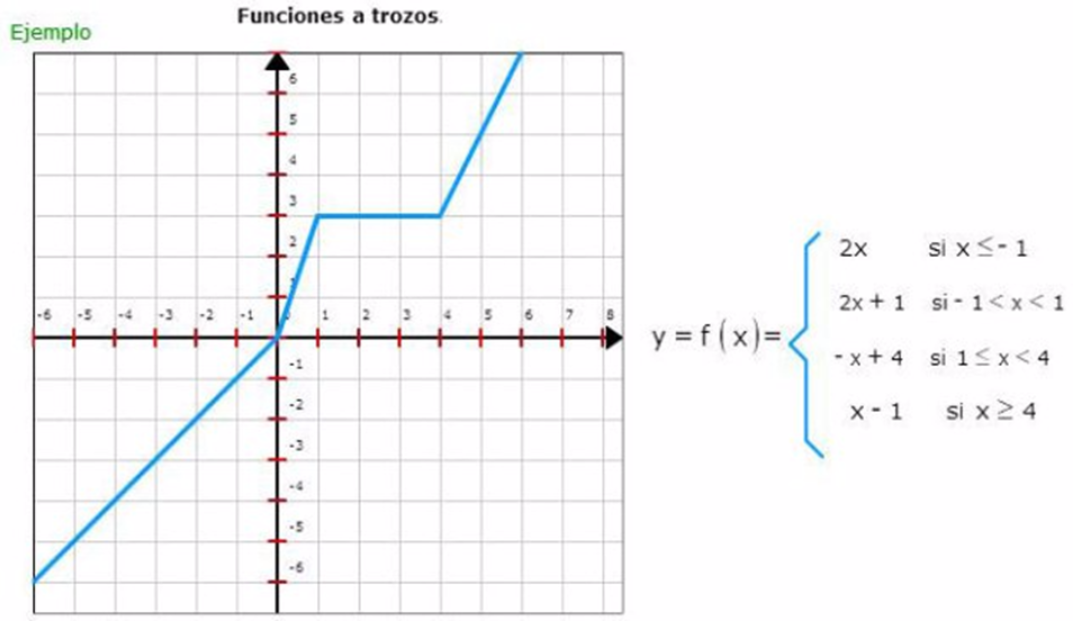

clear
close all
clc

Para determinar los diferentes puntos de la trayectoria, conté las veces que rota y se mueve, definiendo un tiempo total de 8 donde cada intervalo de muestreo es de 1 segundo.

%%% TIEMPO %%%
 
% Definición de parámetros de tiempo
tf = 8;             % Tiempo de simulación en segundos (s)
ts = 1;              % Tiempo de muestreo en segundos (s)

% Creación del vector de tiempo
t = 0:ts:tf;         % Vector de tiempo
N = length(t);       % Número de muestras

%%% CONDICIONES INICIALES %%%

x1 = zeros (1,N+1);  % Posición en el centro del eje que une las ruedas (eje x) en metros (m)
y1 = zeros (1,N+1);  % Posición en el centro del eje que une las ruedas (eje y) en metros (m)
phi = zeros(1, N+1); % Orientacion del robot en radianes (rad)

En este caso, el origen lo definí en (-6,-6) debido a la facilidad que ofrece para poder determinar los ángulos, con una rotación inicial de 0 para encontrar el ángulo inicial con mayor facilidad.

x1(1) = -6;    % Posición inicial eje x
y1(1) = -6;   % Posición inicial eje y
phi(1) = 0;   % Orientación inicial del robot

%%% PUNTO DE CONTROL %%%

hx = zeros(1, N+1);  % Posición en el punto de control (eje x) en metros (m)
hy = zeros(1, N+1);  % Posición en el punto de control (eje y) en metros (m)

hx(1) = x1(1); % Posición en el punto de control del robot en el eje x
hy(1) = y1(1); % Posición en el punto de control del robot en el eje y

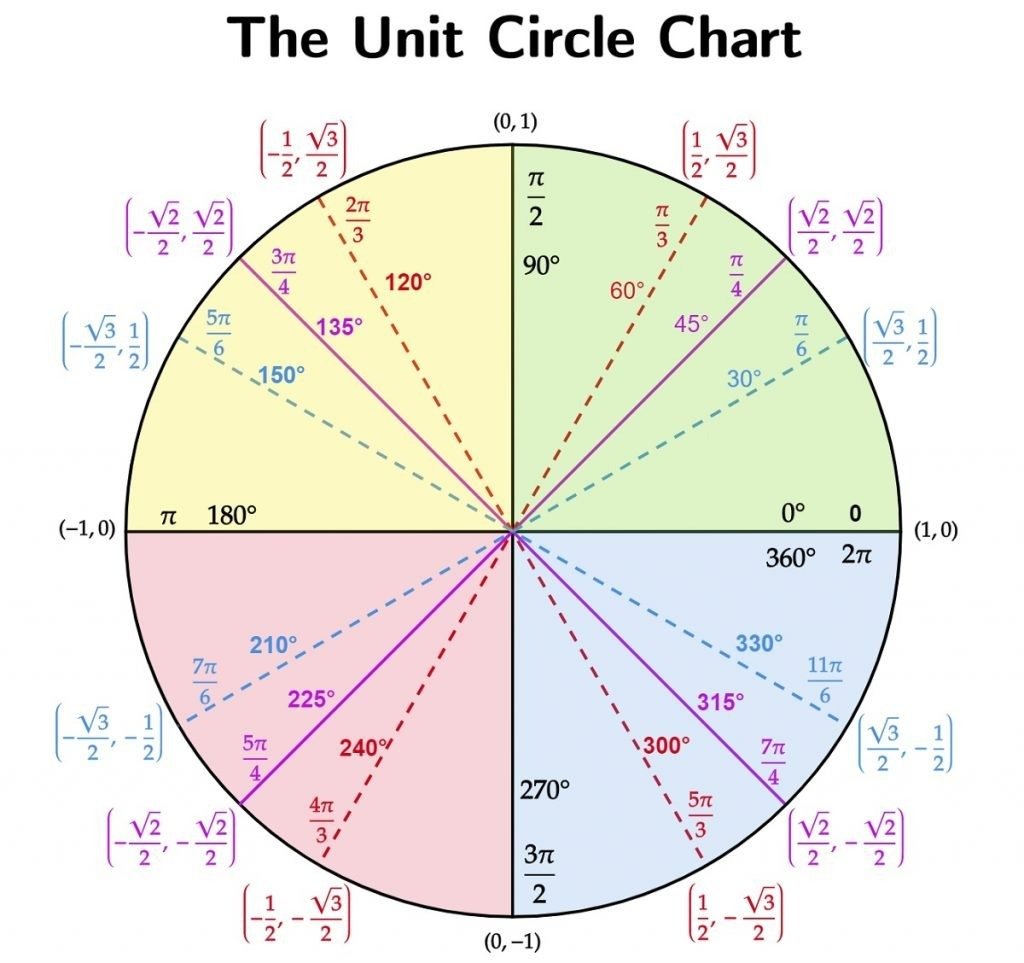

Para determinar las velocidades, fui adaptando los movimientos paso a paso, donde primero considero la rotación y luego los desplazamientos. Consideré la resta entre ángulos para determinar los ángulos entre cada desplazamiento de rotación. Al final, agregué un movimiento de 0 para 𝑢*u* y 𝑤*w* debido a que para graficar debe tener un movimiento final.

%%% VELOCIDADES DE REFERENCIA %%% 
u = [ 0  , 8.49 ,      0        , 3.16 ,       0         , 3 ,  0  ,  3.61, 0 ]; % Velocidad lineal de referencia (m/s)
w = [pi/4,  0   , (pi/3)-(pi/6) , 0    , -(pi/2)+(pi/10) , 0 , pi/4,   0  , 0 ]; % Velocidad angular de referencia (rad/s)

%%% BUCLE DE SIMULACIÓN %%% 
for k=1:N 
    
    phi(k+1)=phi(k)+w(k)*ts; % Integral numérica (método de Euler)
    
    % MODELO CINEMATICO 
    xp1=u(k)*cos(phi(k+1)); 
    yp1=u(k)*sin(phi(k+1));

    x1(k+1)=x1(k) + xp1*ts ; % Integral numérica (método de Euler)
    y1(k+1)=y1(k) + yp1*ts ; % Integral numérica (método de Euler)
    
    % Posición del robot con respecto al punto de control
    hx(k+1)=x1(k+1); 
    hy(k+1)=y1(k+1);

end

% SIMULACION VIRTUAL 3D

% a) Configuración de escena
scene=figure;  % Crear figura (Escena)
set(scene,'Color','white'); % Color del fondo de la escena
set(gca,'FontWeight','bold') ;% Negrilla en los ejes y etiquetas
sizeScreen=get(0,'ScreenSize'); % Retorna el tamaño de la pantalla del computador
set(scene,'position',sizeScreen); % Congigurar tamaño de la figura
camlight('headlight'); % Luz para la escena
axis equal; % Establece la relación de aspecto para que las unidades de datos sean las mismas en todas las direcciones.
grid on; % Mostrar líneas de cuadrícula en los ejes
box on; % Mostrar contorno de ejes
xlabel('x(m)'); ylabel('y(m)'); zlabel('z(m)'); % Etiqueta de los eje

view([-0.1 35]); % Orientacion de la figura
axis([-7 8 -6 8 0 2]); % Ingresar limites minimos y maximos en los ejes x y z [minX maxX minY maxY minZ maxZ]

% b) Graficar robots en la posicion inicial
scale = 4;
MobileRobot_5;
H1=MobilePlot_4(x1(1),y1(1),phi(1),scale);hold on;

% c) Graficar Trayectorias
H2=plot3(hx(1),hy(1),0,'r','lineWidth',2);

% d) Bucle de simulacion de movimiento del robot

step=1; % pasos para simulación

for k=1:step:N

    delete(H1);    
    delete(H2);
    
    H1=MobilePlot_4(x1(k),y1(k),phi(k),scale);
    H2=plot3(hx(1:k),hy(1:k),zeros(1,k),'r','lineWidth',2);
    
    pause(ts);

end